Zad. 1

format long;
s=tf('s');
z=tf('z',0.1);
A=4;
B=1;
a=5;
b=3;
c=1;

G1(s); G2(s)

G1=A/s*B/s/(1+B/s*c*b)

G1 =
 
      4 s
  -----------
  s^3 + 3 s^2
 
Continuous-time transfer function.



G2=c-a*s/B

G2 =
 
  -5 s + 1
 
Continuous-time transfer function.



G_ToruGlownego(z)

G_ToruGlownego = minreal(zpk(c2d(G1,0.1)))

G_ToruGlownego =
 
  0.018141 (z+0.9049)
  -------------------
   (z-1) (z-0.7408)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



G0(z)

G0=minreal(zpk(c2d(G1*G2,0.1)))

G0 =
 
  -1.7097 (z-1.02)
  ----------------
  (z-1) (z-0.7408)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



G(z)

% G=minreal(zpk(c2d(G1/(1+G1*G2),0.1)))
G=G_ToruGlownego/(1+G0); G=minreal(G)

G =
 
  0.018141 (z+0.9049)
  -------------------
  (z-1.024) (z-2.426)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



evalfr(G,1)

ans =    1.000000000000002


5.

% syms K(z);
% K(z)=0.0090707*(z+0.9049)/(z^2 - 2.077*z + 1.095);
% K(1)
evalfr(G,1)

ans =    1.000000000000002


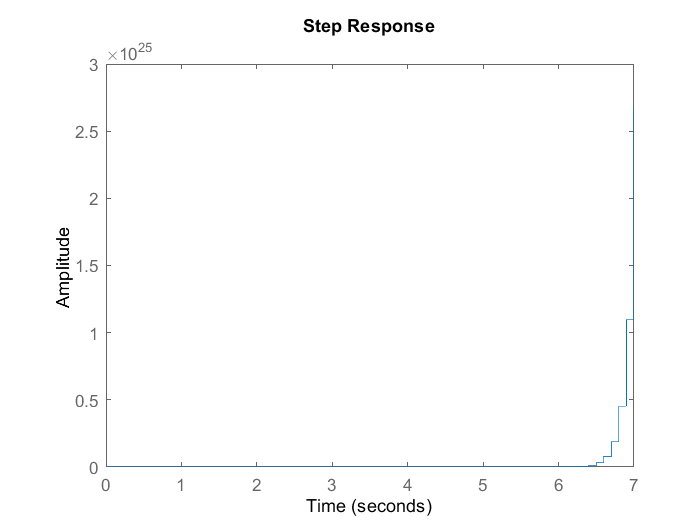

step(G)

7.

[num,den]=tfdata(G,'v')

num =                    0   0.018141431414097   0.016416139161674


den =    1.000000000000000  -3.450555318056168   2.485112888631938


r=roots(den);
abs(r(1));
abs(r(2));

eq=ss(G,'minimal');
eq=ss(G,'explicit')

eq =
 
  A = 
          x1     x2
   x1  1.024  1.389
   x2      0  2.426
 
  B = 
         u1
   x1     0
   x2  0.25
 
  C = 
            x1       x2
   y1   0.1008  0.07257
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



eq=ss(G)

eq =
 
  A = 
          x1     x2
   x1  1.024  1.389
   x2      0  2.426
 
  B = 
         u1
   x1     0
   x2  0.25
 
  C = 
            x1       x2
   y1   0.1008  0.07257
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



Zad. 2

syms s tau f(t) n T z
%tau=0.4

a.

F = 2/s/s/(tau*s+1)

$$F = \frac{2}{s^{2}\,\left(s\,\tau +1\right)}$$

f(t)=ilaplace(F)

$$f(t) = 2\,t-2\,\tau +2\,\tau \,{\mathrm{e}}^{-\frac{t}{\tau }}$$

f(n*T)

$$ans = 2\,T\,n-2\,\tau +2\,\tau \,{\mathrm{e}}^{-\frac{T\,n}{\tau }}$$

y=simplifyFraction(ztrans(f(n*T))*(z-1)/z)

$$y = -\frac{2\,\left(T+\tau -\tau \,z-\tau \,{\mathrm{e}}^{T/\tau }-T\,z\,{\mathrm{e}}^{T/\tau }+\tau \,z\,{\mathrm{e}}^{T/\tau }\right)}{\left(z\,{\mathrm{e}}^{T/\tau }-1\right)\,\left(z-1\right)}$$

y=iztrans(y)

$$y = \left({\left({\mathrm{e}}^{-\frac{T}{\tau }}\right)}^{n}-\delta_{n,0}\right)\,\left(2\,\tau -2\,\tau \,{\mathrm{e}}^{T/\tau }\right)-2\,T\,\left(\delta_{n,0}-1\right)$$

y=simplifyFraction(y)

$$y = -2\,{\mathrm{e}}^{T/\tau }\,\left(\tau \,{\left({\mathrm{e}}^{-\frac{T}{\tau }}\right)}^{n}-T\,{\mathrm{e}}^{-\frac{T}{\tau }}-\tau \,\delta_{n,0}+T\,{\mathrm{e}}^{-\frac{T}{\tau }}\,\delta_{n,0}-\tau \,{\mathrm{e}}^{-\frac{T}{\tau }}\,{\left({\mathrm{e}}^{-\frac{T}{\tau }}\right)}^{n}+\tau \,{\mathrm{e}}^{-\frac{T}{\tau }}\,\delta_{n,0}\right)$$

b.

F = 2/s/(tau*s+1)

$$F = \frac{2}{s\,\left(s\,\tau +1\right)}$$

f(t)=ilaplace(F)

$$f(t) = 2-2\,{\mathrm{e}}^{-\frac{t}{\tau }}$$

f(n*T)

$$ans = 2-2\,{\mathrm{e}}^{-\frac{T\,n}{\tau }}$$

y=ztrans(f(n*T))

$$y = \frac{2\,z}{z-1}-\frac{2\,z}{z-{\mathrm{e}}^{-\frac{T}{\tau }}}$$

y=2*z/(z-1)-2*z/(z-0.2)

$$y = \frac{2\,z}{z-1}-\frac{2\,z}{z-\frac{1}{5}}$$

y=iztrans(y)

$$y = 2-2\,{\left(\frac{1}{5}\right)}^{n}$$

ROBOCZE:

syms t
dirac(t-T)

$$ans = \delta (T-t)$$

G=zpk([],[-2 -1],10)

G =
 
      10
  -----------
  (s+2) (s+1)
 
Continuous-time zero/pole/gain model.



G=c2d(G,0.1111111)

G =
 
   0.055294 (z+0.8948)
  ---------------------
  (z-0.8948) (z-0.8007)
 
Sample time: 0.11111 seconds
Discrete-time zero/pole/gain model.

